x0=0;
L=10;
hp=0.01;
Ta=20;
T0=40;
TL=200;
f=@(x,Tz) [Tz(2);hp*(Tz(1)-Ta)];
x1=odeShooting(f,T0,x0,L,2,10)

x1 = 168.3797

x2=odeShooting(f,T0,x0,L,2,20)

x2 = 285.8980

g=@(z) odeShooting(f,T0,x0,L,2,z)-TL;
zresp=biseccion(g,10,20) %esta es mi Tfinal

zresp = 12.6907

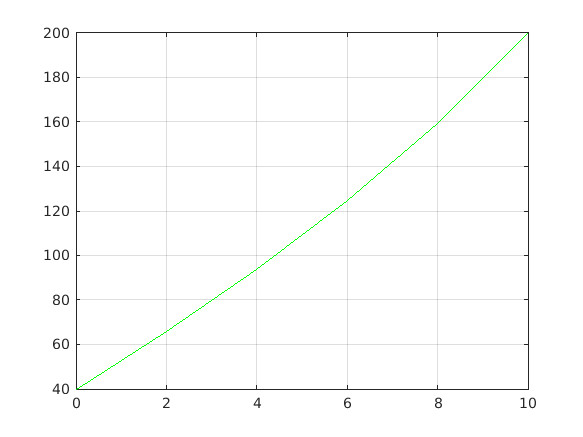

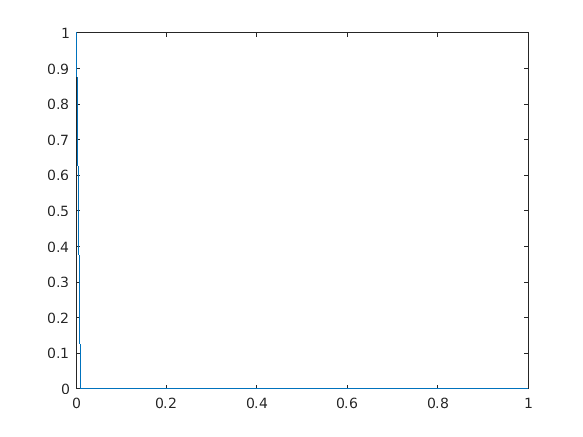

Tz0=[T0,zresp];
[x,T]=odeRK4(f,Tz0,x0,L,2);
plot(x,T(1,:),'g')
grid on